#### Project Fintech, group 2

*Bucci Teo*

*Cipriani Filippo*

*Corbo Gabriele*

*Fabroni Davide*

*Lucchini Marco*

# Estimating Clients' Needs

## Aim: supervised classification of clients and association with his/her preferred product

Our goal is to provide a tool for a financial advisor which supports him in suggesting financial products to his clients.

We intend to estimate some **investments needs **for these customers using **Machine Learning** techniques: we use a bagged tree, optimized with bayesian optimization. After we proceed with the association of the client with his/her preferred product. 

We use two dataset called "Needs" and "Products".

In the first dataset we have a table **Needs**, with some relevant features and two responses:

- "AccumulationInvest" which is about **Accumulation investing**, typically using dollar-cost averaging (you invest small amounts of your money at certain intervals over the course of time); the response is boolean: 1 = high propensity | 0 = low propensity;

- "IncomeInvest" which is about **Income investing**, typically through lump sum investing (one shot); the response is boolean: 1 = high propensity | 0 = low propensity.

In the latter we have a table** Products**  with some products (funds, segregated accounts, unit-linked), their **type** (1 = Accumulation, 0 = Income), and their **risk level** (normalized in the range [0,1]).

#### *Load data*

% File loading
% load('Products.mat')

### **Data transformation of Wealth and Income**

Wealth and Income follow a power law, so it's better to apply some transformation rule.

We chose the **Box Cox** transormation, because it's the one that give us the distribution closer to a normal.

We decided to use an addidional feature, called **Financial Status** as a combination of financial education and wealth: we chose this variable because using R we tried many linear models to predict the risk variable associated with each client, and we saw that this particular trasformation of feature was really influent.

We will cover this part in more detail in the section Predicting RiskPropension

Data = Needs; % renaming (we'll likely manipulate this matrix, but we don't touch the original)
Data.FinancialStatus = Data.FinancialEducation.*log(Data.Wealth)
[boxWealth,p] = boxcox(Data.Wealth);

Data = 5000×11 table
    ID    Age    Gender    FamilyMembers    FinancialEducation    RiskPropensity    Income    Wealth    IncomeInvestment    AccumulationInvestment    FinancialStatus
    __    ___    ______    _____________    __________________    ______________    ______    ______    ________________    ______________________    _______________

    1     60       0             2               0.22868             0.23335        68.182     53.26           0                      1                   0.90906    
    2     78       0             2               0.35892             0.17091        21.808    135.55      

p % 0.1341
histogram(boxWealth); % box-cox transformation

p = 0.1341

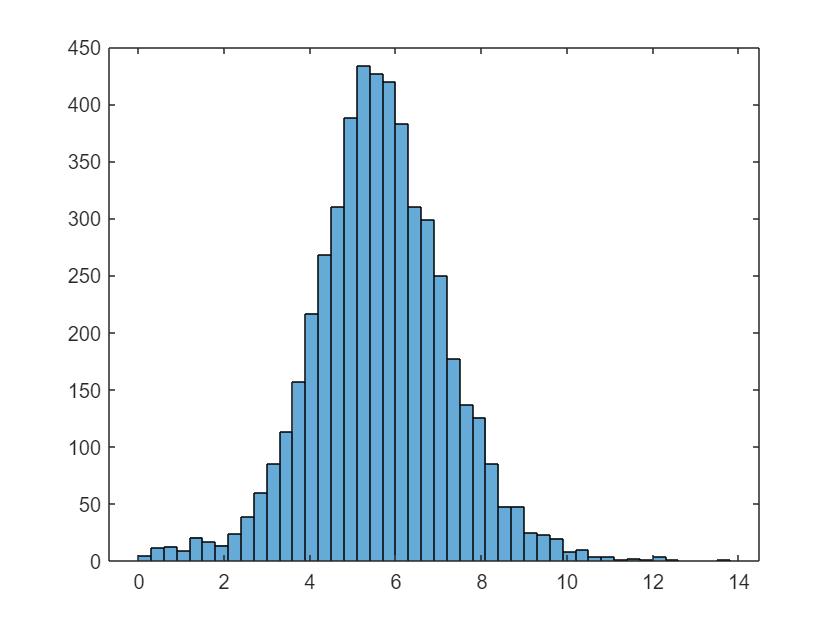

histogram(log(Data.Wealth)) % log transformation

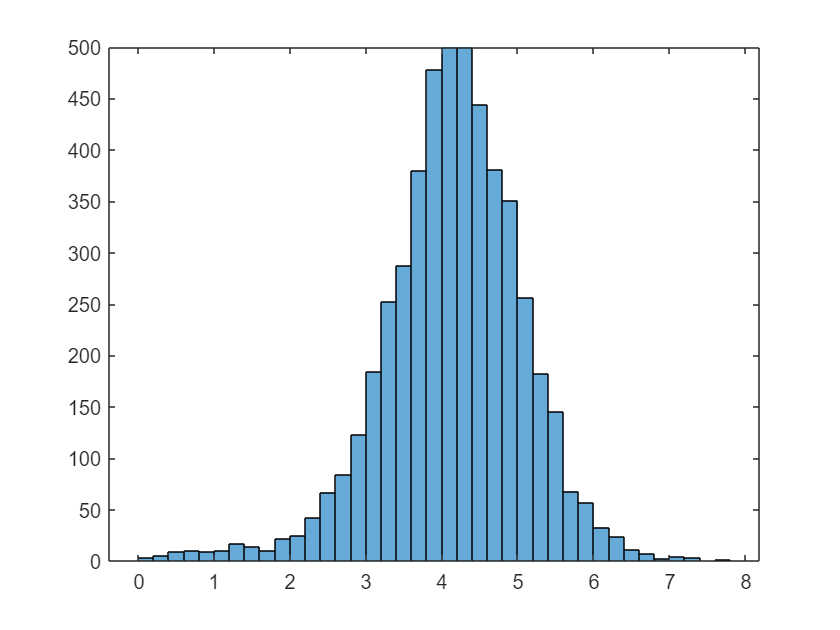

normplot(boxWealth)

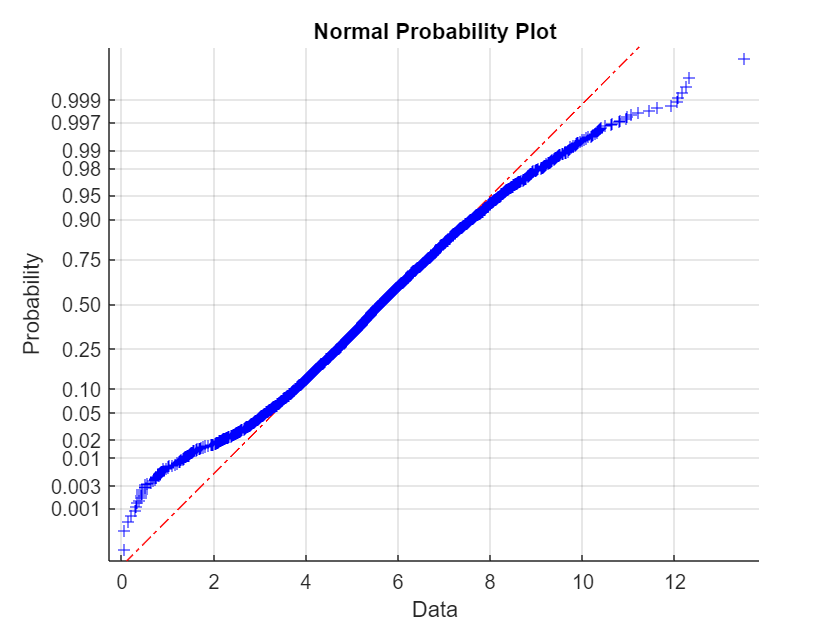

normplot(log(Data.Wealth))  %we chose boxwealth

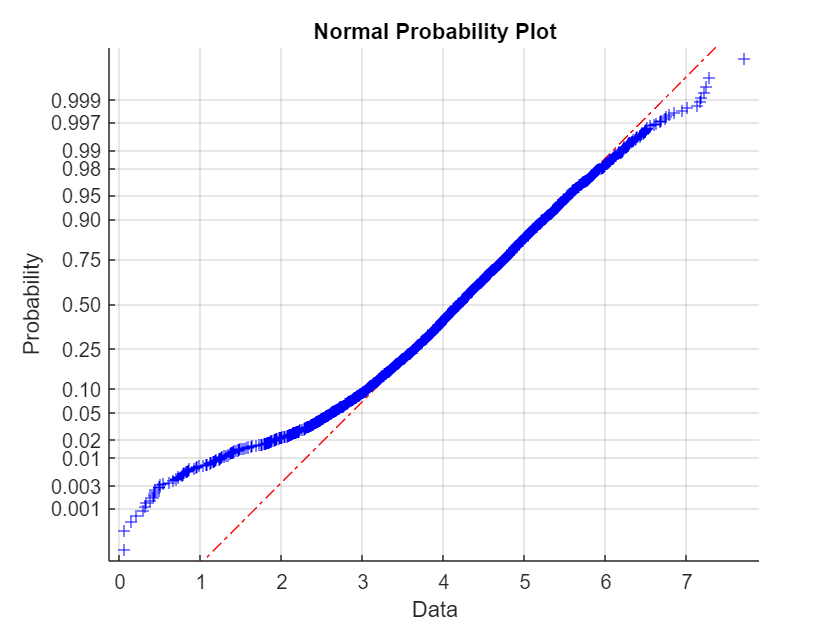

[boxIncome,p] = boxcox(Data.Income);

p % 0.3026
histogram(boxIncome); % box-cox transformation

p = 0.3026

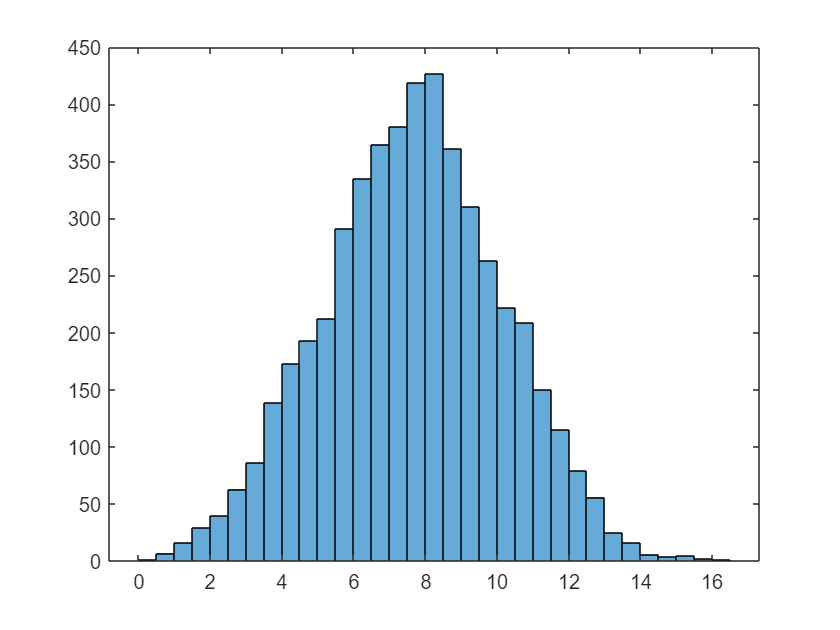

histogram(log(Data.Income)) % log transformation

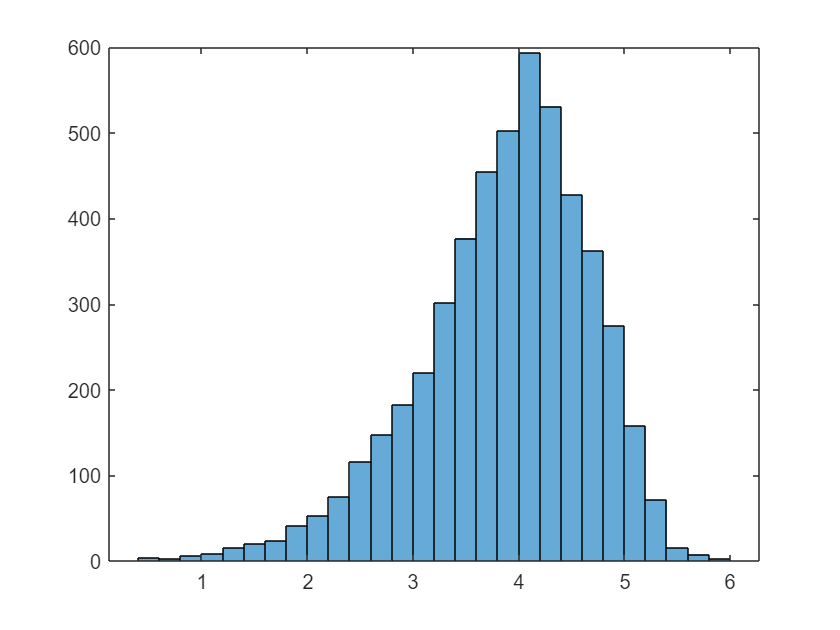

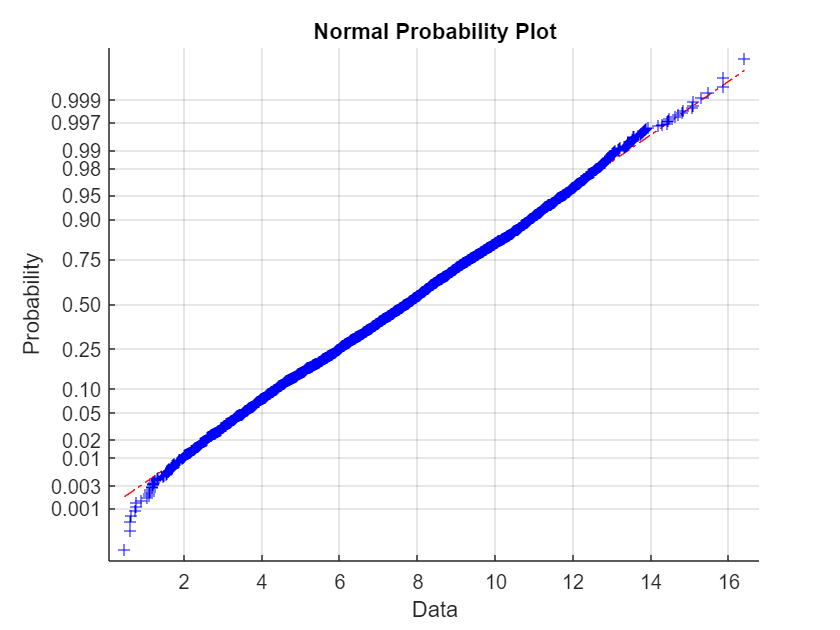

normplot(boxIncome)  % we chose boxIncome

### Data scaling

We will use the min/max rescaling approach in order to make our data comparable before applying the machine learning techniques.

% Min/max rescalation
X =[rescale(Data.Age) Data.Gender rescale(Data.FamilyMembers) rescale(Data.FinancialEducation)...
    rescale(Data.RiskPropensity) rescale(boxIncome) rescale(boxWealth) rescale(Data.FinancialStatus)];

### Dividing our data

We divide data in the training sample and test sample. The proportion we use is 75%-25%;

nObs = size(Data, 1);
rng(10)
idxPermutation = randperm(nObs);
X = X(idxPermutation,:); % random permutation
train = 0.75;    %we choose to use 75% of our dataset to train the model
cross = 0;

nObsTrain = round(train*nObs);
nObsCross = round(cross*nObs);

XTrain = X(1:nObsTrain,:);
XCross = X((nObsTrain+1):(nObsTrain+nObsCross), :);
XTest = X(nObsTrain+1+nObsCross:end,:);


%********* Here we add the same permutation of X on Y   ********
YInc = Data.IncomeInvestment;
YInc = YInc(idxPermutation);

yInvIncTrain = YInc(1:nObsTrain);
yInvIncCross = YInc((nObsTrain+1):(nObsTrain+nObsCross));
yInvIncTest = YInc(nObsTrain+nObsCross+1:end);

YAcc = Data.AccumulationInvestment;
YAcc = YAcc(idxPermutation);

yInvAccTrain = YAcc(1:nObsTrain);
yInvAccCross = YAcc((nObsTrain+1):(nObsTrain+nObsCross));
yInvAccTest = YAcc(nObsTrain+nObsCross+1:end);
%Creation of the tables
varNames = {'Age', 'Gender', 'Family', 'FinEdu', 'Risk', 'Income', 'Wealth','FinancialStatus'};
XTrainTable=table(XTrain(:,1), XTrain(:,2), XTrain(:,3), XTrain(:,4), XTrain(:,5), XTrain(:,6),XTrain(:,7),XTrain(:,8), 'VariableNames',varNames);
XTestTable=table(XTest(:,1), XTest(:,2), XTest(:,3), XTest(:,4), XTest(:,5), XTest(:,6),XTest(:,7),XTest(:,8), 'VariableNames',varNames);
XTable=table(X(:,1), X(:,2), X(:,3), X(:,4), X(:,5), X(:,6),X(:,7),X(:,8), 'VariableNames',varNames);

### Predicting RiskPropensity

We think that estimating the parameter risk is a critical step because it’s a bit unrealistic that a customer knows by himself how much he wants to risk in a 0-1 scale: for example to avoid this problem the popular roboadvisor moneyfarm uses a short questionary to estimate the parameter.

In particular we decided to rely on **MiFID** (acronym for Directive on Markets in Financial Instruments) that is a Community directive aimed at regulating investment services in the 30 Member States.

The MiFID questionnaire aims to collect as much information as possible relating to the knowledge and experience of a client's investments, investment objectives and financial situation, and it is used as a adequacy and appropriateness questionnaire to find the solution more suitable for the client.

Since some of the parameters asked in the MiFid are contained in the needs dataset, we decided to estimate the risk using a regression learner, in particular the **Linear Regression** already implemented in matlab.

We used all the parameters except the gender, since we noticed it wasn't significant in the model, and as already said we added a new feature to improve the accuracy of the model.

Xtopred = X(1:nObsTrain,:);
Xtopred(:,5) = [];
risk = X(1:nObsTrain,5);

XtopredTest = X(nObsTrain+nObsCross+1:end,:);
XtopredTest(:,5) = [];
riskTest = X(nObsTrain+nObsCross+1:end,5);

RiskPred = fitlm(Xtopred,risk)
plot(RiskPred) % plot of adjusted y
% Estimation of the errors
yfit = predict(RiskPred, XtopredTest);

RiskPred = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7

Estimated Coefficients:
                   Estimate     SE    tStat    pValue
                   _________    __    _____    ______

    (Intercept)      0.12713    0      Inf       0   
    x1              -0.30791    0     -Inf       0   
    x2             0.0043705    0      Inf       0   
    x3              0.054196    0      Inf       0   
    x4               0.56213    0      Inf       0   
    x5             -0.083649    0     -Inf       0   
    x6               0.40918    0      Inf       0   
    x7              0.034675    0      Inf       0   


Number of observations: 3750, Error degrees of freedom: 3742
R-squared: 1,  Adj

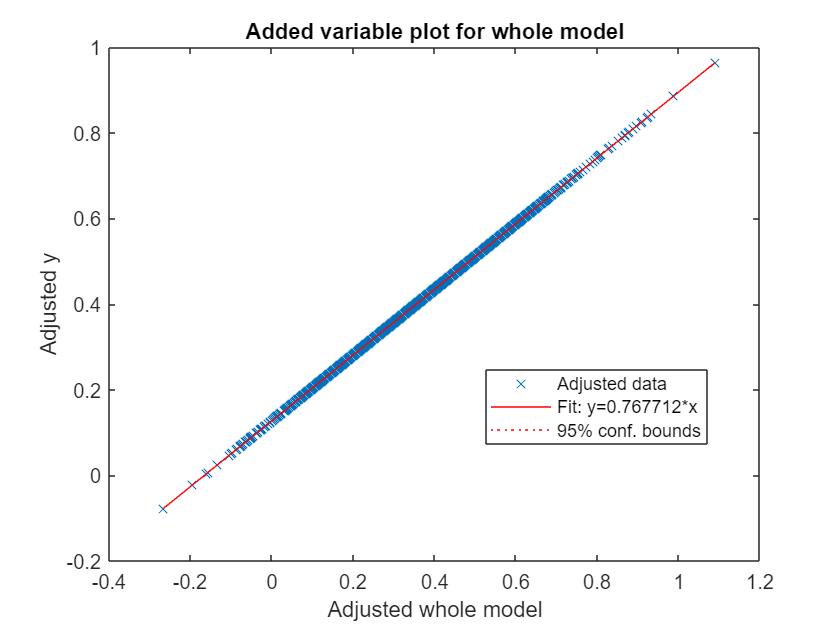

MAE = mean(abs(yfit-riskTest));

adjMAE = MAE/range(riskTest);
errors = [MAE adjMAE]
XtopredFull = X;
XtopredFull(:,5) = [];
yfit = predict(RiskPred, XtopredFull);

errors = 	1.0e+-16 *

    0.7310    0.8127



X(:,5)=yfit;

### Classification models

We follow the financial advisory best practice to refine the process:

- accumulation investment products are mainly intended for relatively young people who have more income than accumulated wealth;

- the "income" investment products are mostly intended for a public that has already accumulated a wealth, and is often older;

- since the Y's derive from the behavior of financial advisors who hopefully follow this practice, an interesting variable is the ratio income / wealth ratio (eliminating the subjects with too low wealth, otherwise the ratio would explode, and besides that they are not too important in terms of business);

- in order to have a cleaner picture I try to eliminate family size and gender, which are perhaps not so decisive (in principle, from a financial advisory perspective they shouldn't be so important). Even risk propensity shouldn't be so important in order to estimate financial needs (it's important in order to choose the right risk level given the product).

xnames = {'Income/Wealth ratio','Age', 'Financial Education', 'Income', 'Wealth'};
IncomeWealthRatio = zeros(nObs,1);
IncomeWealthRatio(Data.Wealth>10) = boxIncome(Data.Wealth>10)./boxWealth(Data.Wealth>10);
Xsmall = [rescale(IncomeWealthRatio) rescale(Data.Age) rescale(Data.FinancialEducation) boxIncome boxWealth];

Back to the classification learner to see what happens: we create a smaller data table.

XsmallTrain = Xsmall(1:nObsTrain,:);
XsmallTest = Xsmall(nObsTrain+1:end,:);
XsmallTrainTable=table(XsmallTrain(:,1), XsmallTrain(:,2), XsmallTrain(:,3), XsmallTrain(:,4), XsmallTrain(:,5), 'VariableNames',xnames);

### Fitting the optimized bagged trees

First of all, we prepare our model.

We fit an optimal ensemble of learners for classification: we automatically optimize ensemble hyperparameters using the function `fitcensemble.` It finds hyperparameters that minimize k-fold cross-validation loss (with K=5) by using automatic hyperparameter optimization. As we specify `'OptimizeHyperparameters'`, the function finds optimal parameters automatically using Bayesian optimization.

% Accumulation fitting
rng('default')
t = templateTree('Reproducible',true); % in order to get reproducible results
MdlOptimum_acc = fitcensemble(XsmallTrainTable,yInvAccTrain,'OptimizeHyperparameters','auto','Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))
% Income fitting
rng('default')
t = templateTree('Reproducible',true); % in order to get reproducible results
MdlOptimum_inc = fitcensemble(XsmallTrainTable,yInvIncTrain,'OptimizeHyperparameters','auto','Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))
% We save the models
save("model_accTIME.mat","MdlOptimum_acc");
save("model_incTIME.mat","MdlOptimum_inc");
%load("model_accTIME.mat")
%load("model_incTIME.mat")

## Prediction

From each ensemble classifier, `MdlOptimum_acc` and `MdlOptimum_inc` we retrieve:

- predicted labels;

- scores (the confidence that an observation originates from a specific class; the higher the score, the higher the confidence;  `Bag` scores range from `0` to `1: `closer they are to 1 better is the performance of the classification model.

We examine scores,which are probabilities averaged over all the trees in the ensemble, in order to understand how strong is the model conviction.

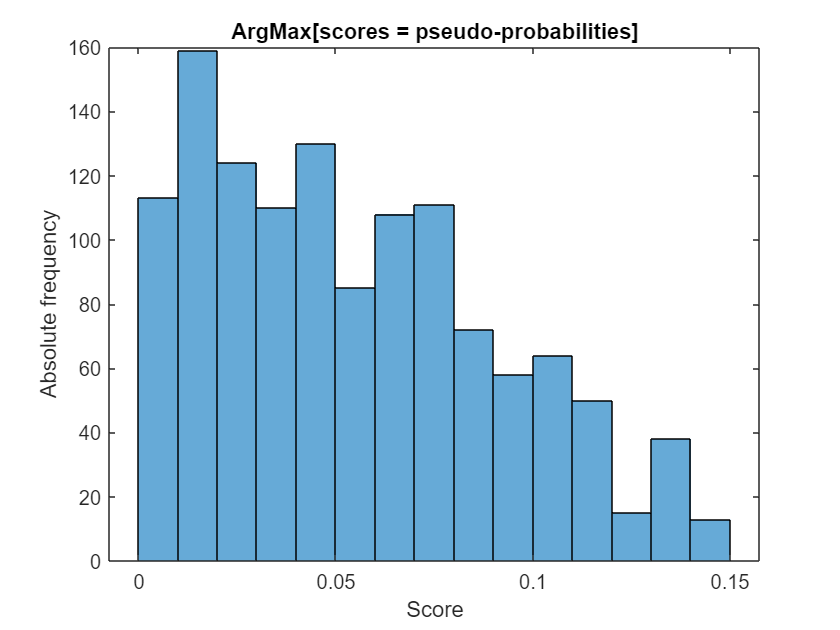

[labels_acc,scores_acc] = predict(MdlOptimum_acc,XTest);

figure
histogram(max(scores_acc')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')

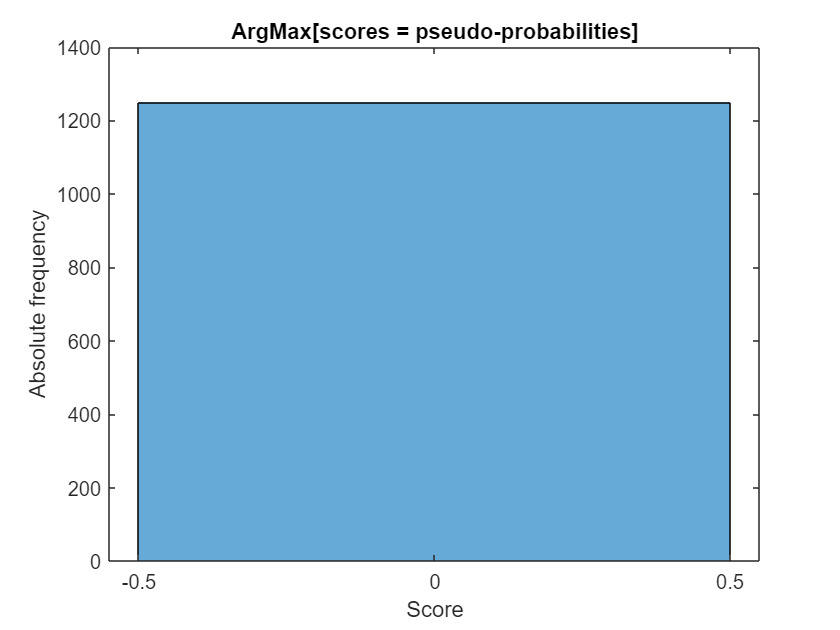

ylabel('Absolute frequency')
[labels_inc,scores_inc] = predict(MdlOptimum_inc,XTest);

figure
histogram(max(scores_inc')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')

ylabel('Absolute frequency')

We observe that most scores are close to 1, therefore the model has a strong convinction of its predictions.

### Analysis of the results of the model

Let's compute **Precision**, **Recall**, and the **F1 score**, which tell how well the model classifies correctly the Accumulation need of clients to their true value.

% Accumulation products
tp_acc = sum((labels_acc == '1') & (yInvAccTest=='1'));
fp_acc = sum((labels_acc == '1') & (yInvAccTest=='0'));
fn_acc = sum((labels_acc == '0') & (yInvAccTest=='1'));

prec_acc = 0.5188

prec_acc = tp_acc / (tp_acc + fp_acc)

rec_acc = 0.5975

rec_acc = tp_acc / (tp_acc + fn_acc)

F1_acc = 0.5554

F1_acc = 2 * prec_acc * rec_acc / (prec_acc + rec_acc)

### Precision, recall and F1 score for Accumulation need

Let's compute **Precision**, **Recall**, and the **F1 score**, which tell how well the model classifies correctly the Income need of clients to their true value.

% Income products
tp_inc = sum((labels_inc == '1') & (yInvIncTest=='1'));
fp_inc = sum((labels_inc == '1') & (yInvIncTest=='0'));
fn_inc = sum((labels_inc == '0') & (yInvIncTest=='1'));

prec_inc = NaN

prec_inc = tp_inc / (tp_inc + fp_inc)

rec_inc = 0

rec_inc = tp_inc / (tp_inc + fn_inc)

F1_inc = NaN

F1_inc = 2 * prec_inc * rec_inc / (prec_inc + rec_inc)

In both cases the results indicate that the model classifies Accumulation and Income need, since precision, recall and F1 score are quite close to 1.

### ROC curve

[X_acc,Y_acc,T_acc,AUC_acc,OPTROCPT_acc] = perfcurve(yInvAccTest,scores_acc(:,2),1);
%area under curve

AUC_acc = 0.5051

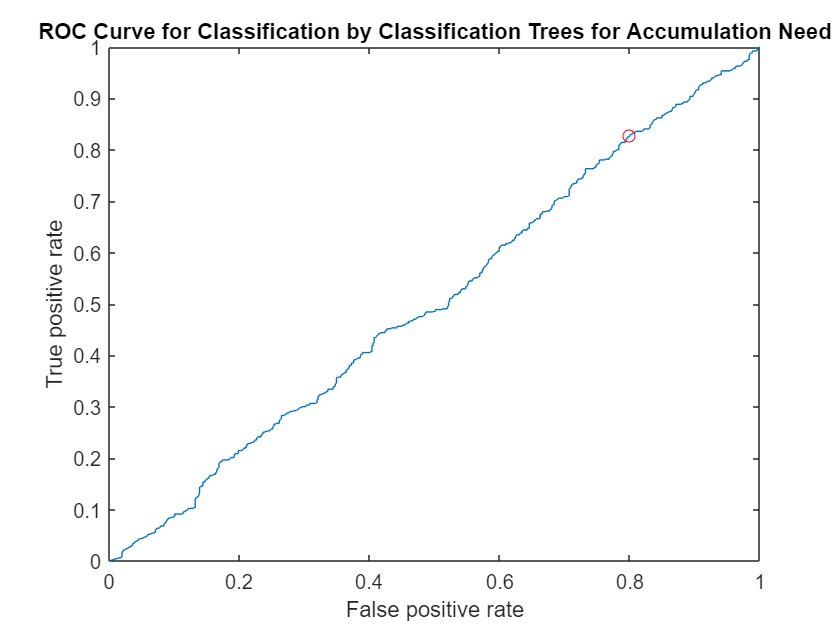

AUC_acc   %good value of AUC
plot(X_acc,Y_acc)
hold on
plot(OPTROCPT_acc(1),OPTROCPT_acc(2),'ro')
xlabel('False positive rate')
ylabel('True positive rate')
title('ROC Curve for Classification by Classification Trees for Accumulation Need')

hold off
%optimal operating point accumulation

OPTROCPT_acc =     0.7997    0.8282


OPTROCPT_acc
%threshold of the optimal operating point

ans = -0.0484

T_acc((X_acc==OPTROCPT_acc(1))&(Y_acc==OPTROCPT_acc(2)))
%income
[X_inc,Y_inc,T_inc,AUC_inc,OPTROCPT_inc] = perfcurve(yInvIncTest,scores_inc(:,2),1);
%area under curve

AUC_inc = 0.5000

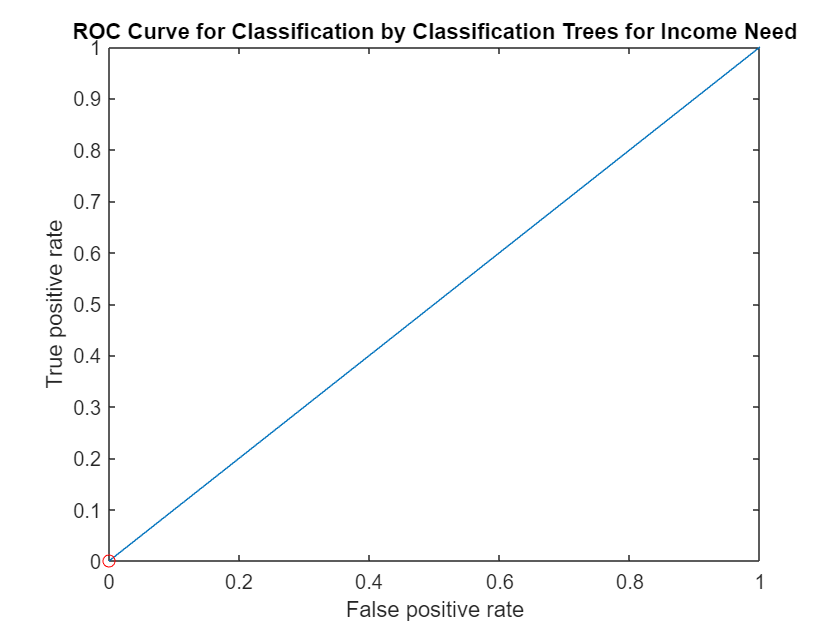

AUC_inc
plot(X_inc,Y_inc)
hold on
plot(OPTROCPT_inc(1),OPTROCPT_inc(2),'ro')
xlabel('False positive rate')
ylabel('True positive rate')
title('ROC Curve for Classification by Classification Trees for Income Need')

hold off
%optimal operating point accumulation

OPTROCPT_inc =      0     0


OPTROCPT_inc
%threshold of the optimal operating point

ans = -0.0762

T_inc((X_inc==OPTROCPT_inc(1))&(Y_inc==OPTROCPT_inc(2)))

 The ROC curves show the goodness-of-fit of the model considered. It plots the trade-off between sensitivity (or TPR) and specificity (1 – FPR). 

This curves confirm that our models provide an accurate classification. Moreover the value of the AUC is very close to 1 in both cases.

We observe that the classification of accumulation needs is a bit more accurate than the income ones.

### **Confusion matrices**

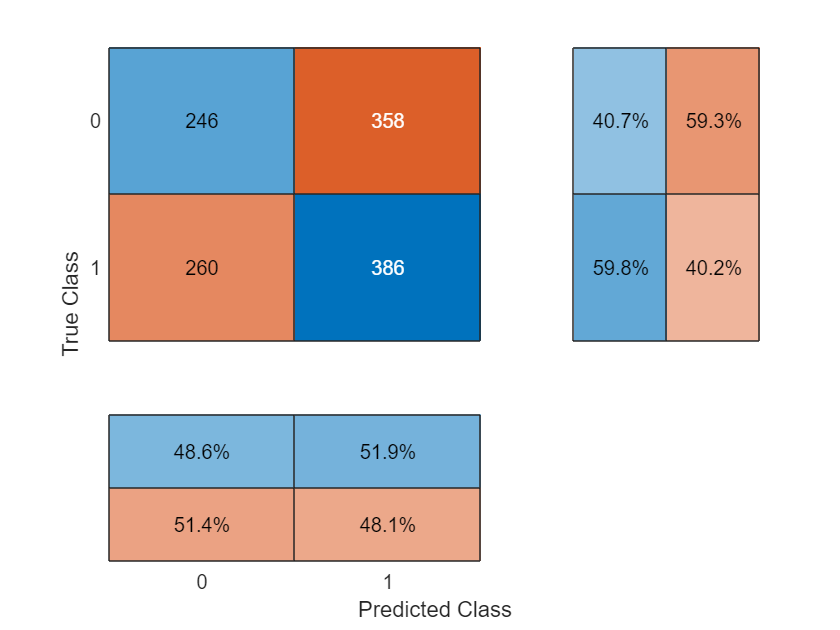

%  Specify 'RowSummary' as 'row-normalized' to display the true positive rates and false positive rates in the row summary.
%  Also, specify 'ColumnSummary' as 'column-normalized' to display the positive predictive values and false discovery rates in the column summary.

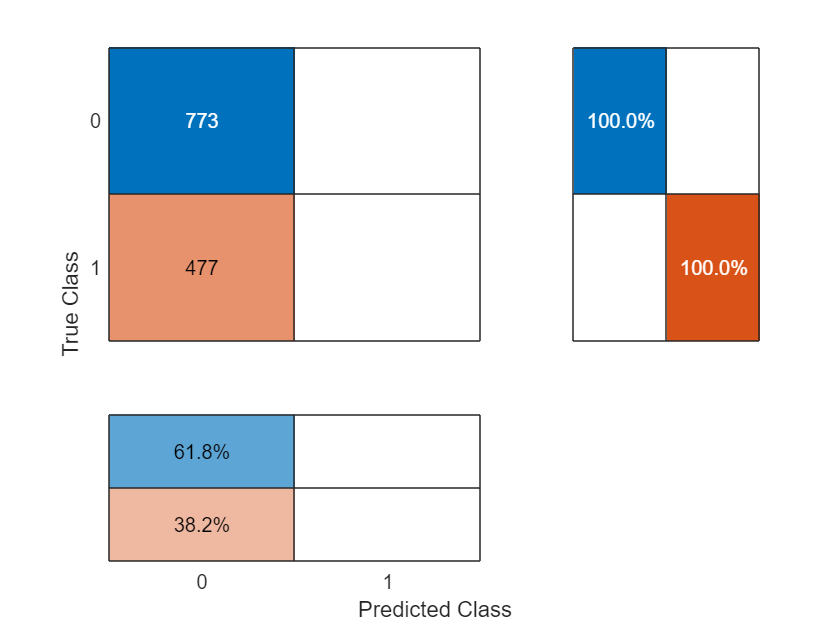

confusionchart(yInvAccTest,labels_acc,'RowSummary','row-normalized','ColumnSummary','column-normalized');
%  Specify 'RowSummary' as 'row-normalized' to display the true positive rates and false positive rates in the row summary.
%  Also, specify 'ColumnSummary' as 'column-normalized' to display the positive predictive values and false discovery rates in the column summary.

confusionchart(yInvIncTest,labels_inc,'RowSummary','row-normalized','ColumnSummary','column-normalized');

In both cases the model could be improved by reducing the number of false positives: is predicted 0 (no need of accumulation or income product) instead of a true 1 (a need in one of the two).

## Recommending products

Now we generate the personalized recommendation for both the Accumulation products (that is, Products.Type==1) and for the Income Products (that is, Products.Type==0).

We adopt the following rules, for each client:

- **matching product type and client need (predicted using the ensemble model)**;

- **matching product risk and client risk**;

- **suggesting a list of products**, ranked based on a decreasing risk.

For simplicity and to continue the example, we do that for the clients in the test set (but the rules work for an arbitrary set of clients).

Retrieving IDs and risk propensities for the client in the test set, and products (using the variable idxPermutation).

% Retrieving clients IDs
ClientID = Data.ID(idxPermutation);
ClientIDTest = ClientID(nObsTrain+1:end,:);
TargetClientID_acc = ClientIDTest(labels_acc=='1');
TargetClientID_inc = ClientIDTest(labels_inc=='1');

% Retrieving clients' risk propensities
ClientRiskPropensity = Data.RiskPropensity(idxPermutation);
ClientRiskPropensityTest = ClientRiskPropensity(nObsTrain+1:end,:);
TargetClientRiskPropensity_acc = ClientRiskPropensityTest(labels_acc=='1');
TargetClientRiskPropensity_inc = ClientRiskPropensityTest(labels_inc=='1');

% Retrieving clients' time horizon
ClientTimeHorizon= Data.InvestmentTimeHorizon(idxPermutation);
ClientTimeHorizonTest = ClientTimeHorizon(nObsTrain+1:end,:);
TargetClientTimeHorizon_acc = ClientTimeHorizonTest(labels_acc=='1');
TargetClientTimeHorizon_inc = ClientTimeHorizonTest(labels_inc=='1');

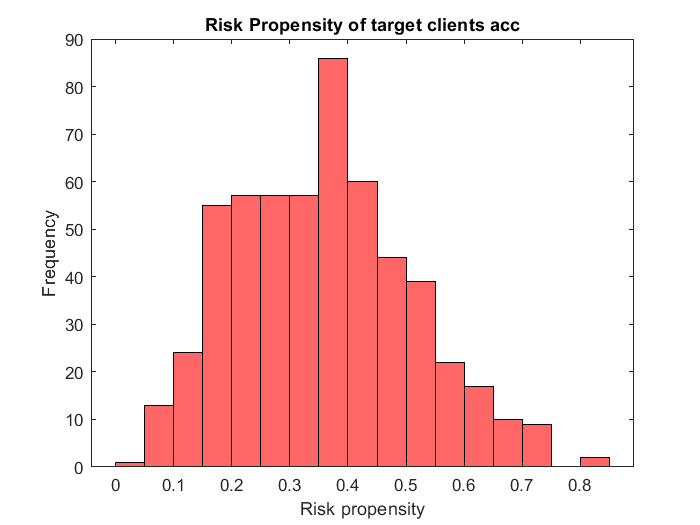

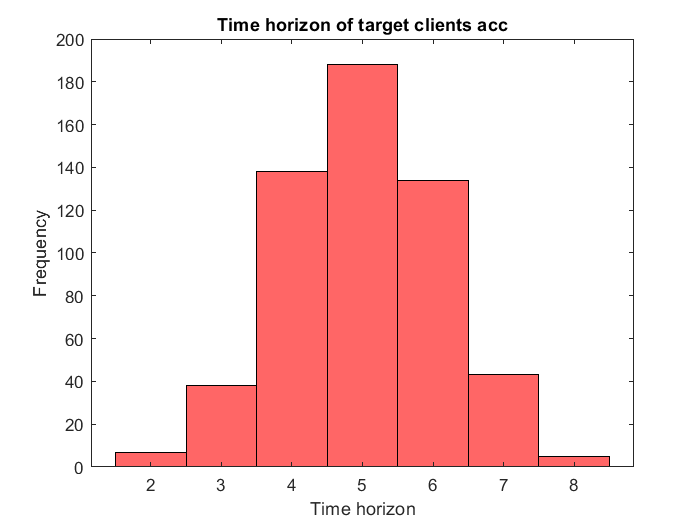

% Let's have a look to risk propensities and time horizon
figure
histogram(TargetClientRiskPropensity_acc, 'FaceColor', 'r')

title('Risk Propensity of target clients acc')
xlabel('Risk propensity')
ylabel('Frequency')

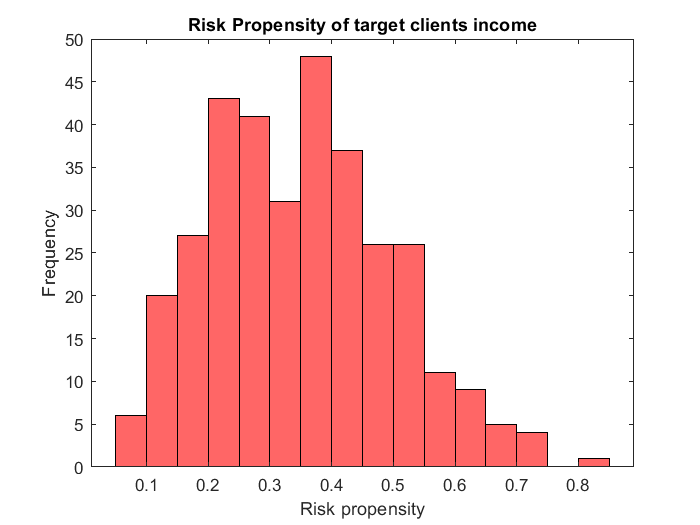

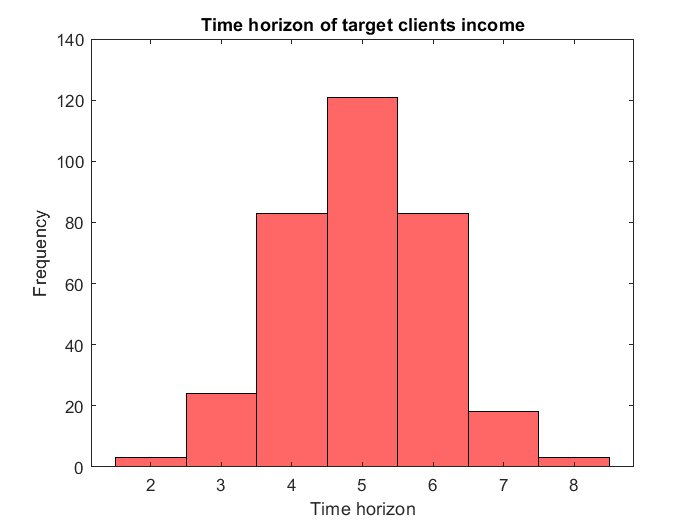

IncomeProducts = 5×4 table
    ID    Type    Risk    TimeHorizon
    __    ____    ____    ___________

     2     0       0.3         5     
     3     0      0.12         8     
     4     0      0.44         7     
    10     0      0.13         8     
    12     0      0.05         2     


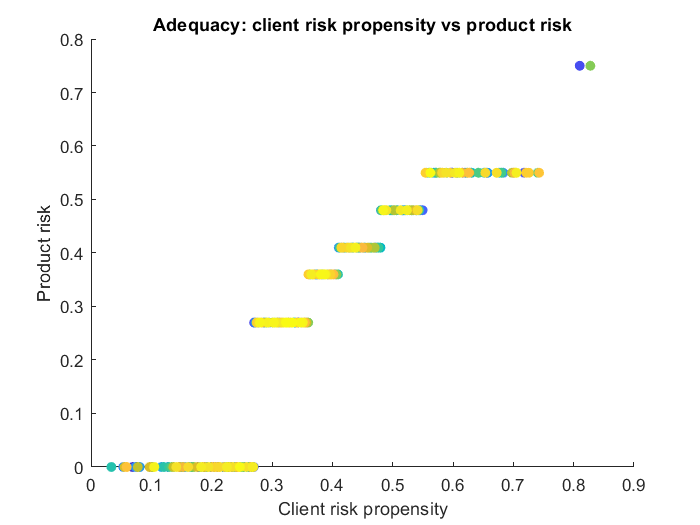

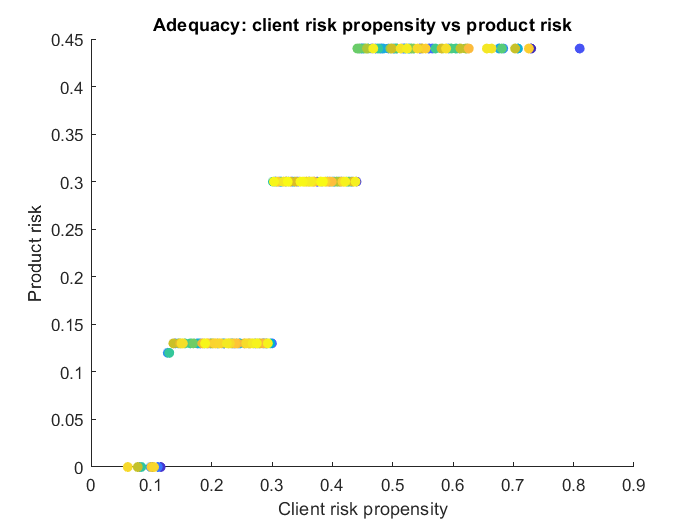

figure
histogram(TargetClientRiskPropensity_inc, 'FaceColor', 'r')
title('Risk Propensity of target clients income')

xlabel('Risk propensity')
ylabel('Frequency')